tRange = [0 200]

tRange =      0   200


Y0 = [0.99; 0; 0.01; 0]

Y0 =     0.9900
         0
    0.0100
         0


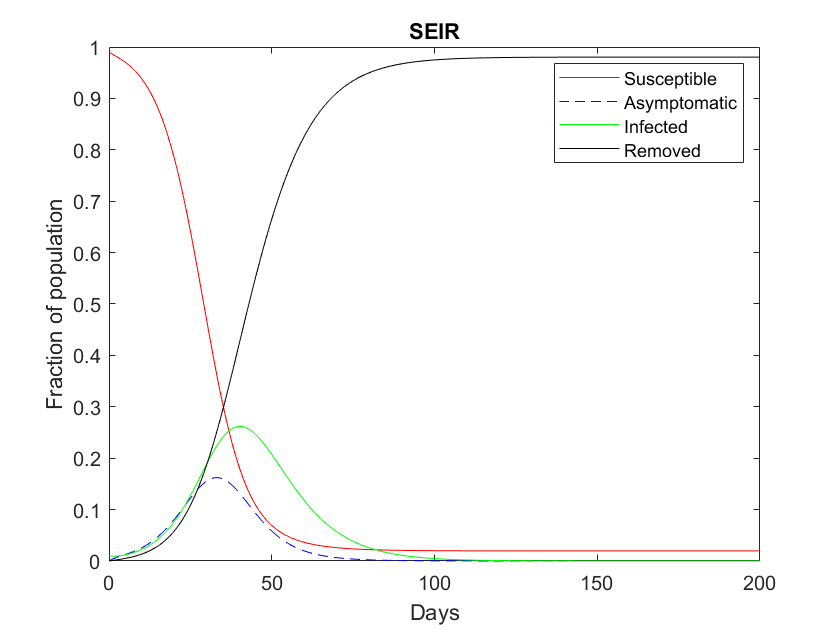

[tSol,YSol] = ode45(@sir,tRange,Y0);
clf()
plot(tSol,YSol(:,1),'r')
hold on
plot(tSol,YSol(:,2),'b--')
plot(tSol,YSol(:,3),'g')
plot(tSol,YSol(:,4),'k')
title("SEIR")
xlabel("Days")
ylabel("Fraction of population")
legend("Susceptible","Asymptomatic","Infected","Removed")
hold off

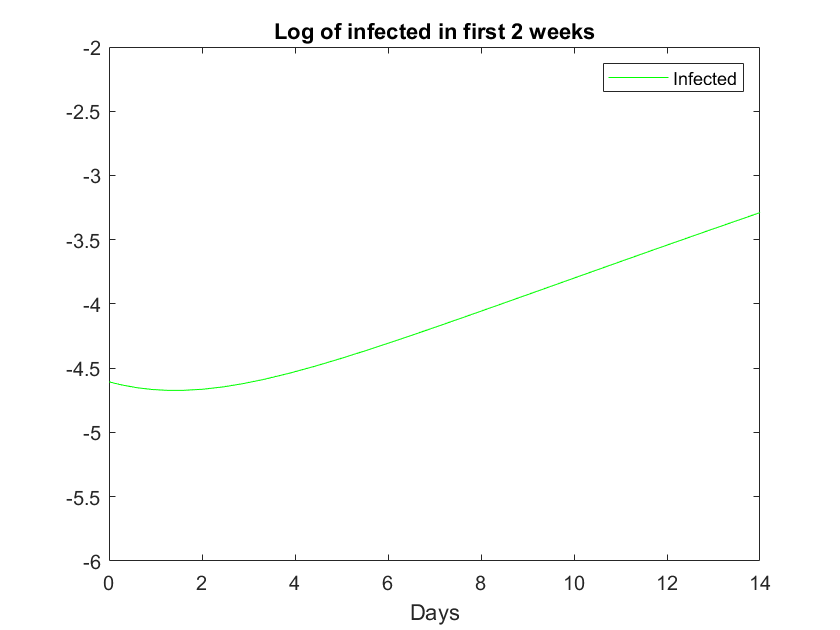

plot(tSol,log(YSol(:,3)),'g')
axis([0 14 -6 -2])
title("Log of infected in first 2 weeks")
xlabel("Days")
legend("Infected")

function dYdt = sir(t,Y)
    S = Y(1);
    E = Y(2);
    I = Y(3);
    R = Y(4);
    a = 0.4;
    r = 0.1;
    c = 0.2;
    B = 0.00000000001;
    d = 0.00000000001;
    dSdt = B - a*S*I - d*S;
    dEdt = a*S*I - c*E - d*E;
    dIdt = c*E - r*I - d*I;
    dRdt = r*I - d*R;
    
    dYdt = [dSdt;dEdt;dIdt;dRdt];
    n = S + I + E + R; %% Sanity Check %%
end
